## 导入数据

clear;warning off;
data=readmatrix("all_data_first.xlsx")

data =    77.9200   72.6100   87.9000
   83.7300   77.9300   90.6500
   76.8300   71.5000   90.3800
   80.3600   74.0600   93.4600
   77.4200   68.7500   86.4000
   75.4300   59.8900   86.6800
   75.0200   67.4300   89.9400
   83.0400   76.5200   95.2300
   85.8200   81.0900   91.4700
   87.9100   86.4700   95.6200


## 整体趋势查看

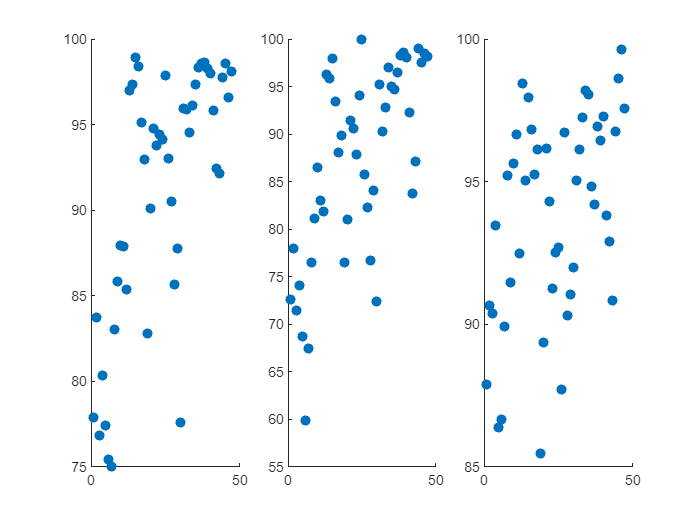

for i=1:3
    subplot(1,3,i)
    x=1:length(data(:,i));
    y=data(:,i);
    scatter(x,y,"filled")
end

data_t=data(:,1);

y_h_adf = adftest(data_t)

y_h_adf = logical
   0


y_h_kpss = kpsstest(data_t)

y_h_kpss = logical
   1


得到y_h_adf =0，y_h_kpss =1，没有通过检验。

% 一阶差分，结果平稳。如果依旧不平稳的话，再次求差分，直至通过检验
Yd1 = diff(data_t);
yd1_h_adf = adftest(Yd1)

yd1_h_adf = logical
   1


yd1_h_kpss = kpsstest(Yd1)

yd1_h_kpss = logical
   0


得到yd1_h_adf =1，yd1_h_kpss =0，通过检验了。

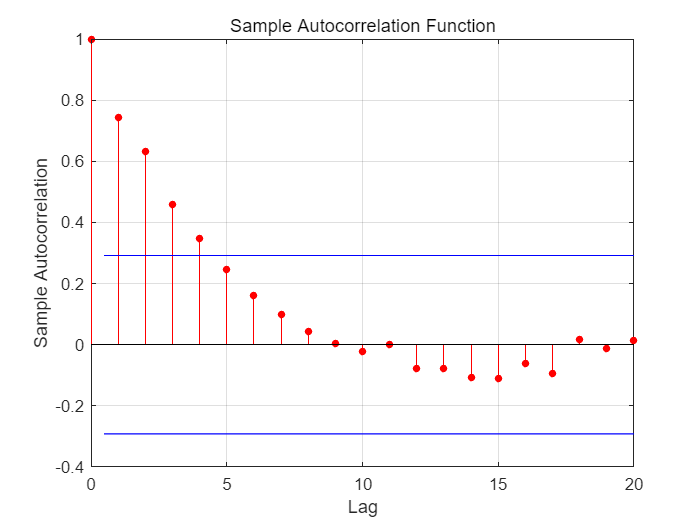

% ACF和PACF法，确定阶数
figure
autocorr(data_t)

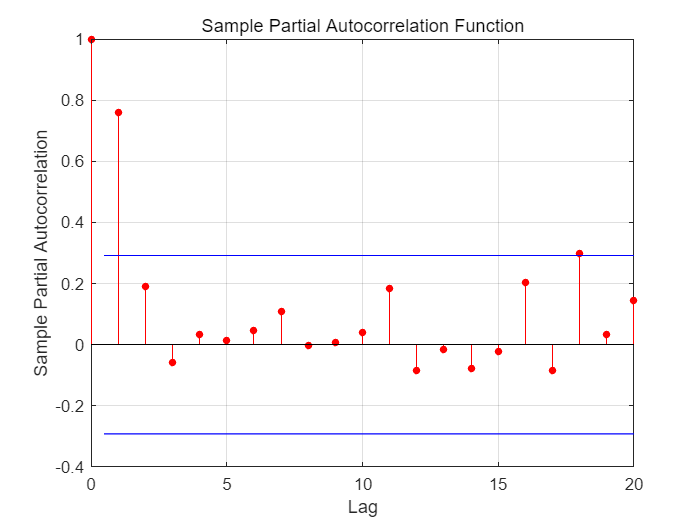

figure
parcorr(data_t)

如图，p定位到2，q定位到4

即`AR_Order=2`

`MA_Order=4`

AR_Order=2;
MA_Order=4;

Mdl = arima(AR_Order, 1, MA_Order);  
%第二个变量值为1，即一阶差分
EstMdl = estimate(Mdl,data_t);

 
    ARIMA(2,1,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.33065        0.2414          1.3697        0.17077
    AR{1}        -0.31469       0.36321         -0.8664        0.38627
    AR{2}         0.46433        0.3331          1.3939        0.16333
    MA{1}        -0.10615       0.45816        -0.23169        0.81678
    MA{2}        -0.70415       0.30475         -2.3106       0.020854
    MA{3}       -0.039141       0.38204        -0.10245         0.9184
    MA{4}        -0.15056       0.30519        -0.49332        0.62179
    Variance       17.575        4.3066          4.0809     4.4871e-05



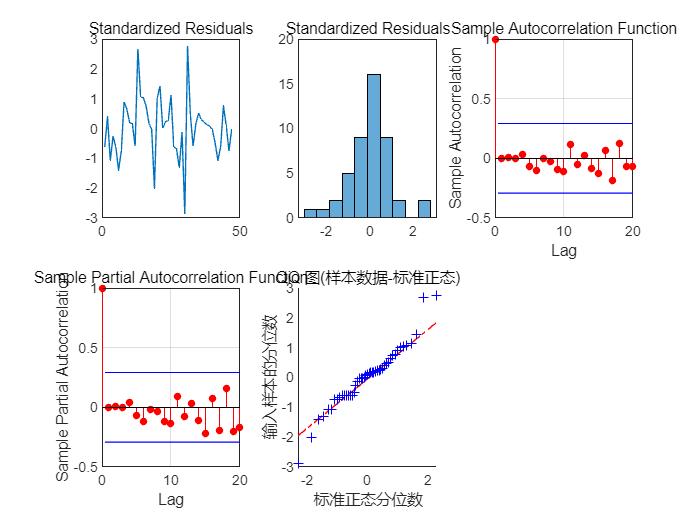

[res,~,logL] = infer(EstMdl,data_t);   
%res即残差

stdr = res/sqrt(EstMdl.Variance);
figure('Name','残差检验')
subplot(2,3,1)
plot(stdr)
title('Standardized Residuals')
subplot(2,3,2)
histogram(stdr,10)
title('Standardized Residuals')
subplot(2,3,3)
autocorr(stdr)
subplot(2,3,4)
parcorr(stdr)
subplot(2,3,5)
qqplot(stdr)

上图为残差检验的结果图。Standardized Residuals是查看残差是否接近正态分布，理想的残差要接近正态分布；ACF和PACF检验残差的自相关和偏自相关，理想的结果应该在图中不存在超出蓝线的点；最后一张QQ图是检验残差是否接近正太分布的，图中中大部分蓝点靠近红线。

% Durbin-Watson 
% 统计是计量经济学分析中最常用的自相关度量
diffRes0 = diff(res);  
SSE0 = res'*res;
DW0 = (diffRes0'*diffRes0)/SSE0 

DW0 = 1.9891

% Durbin-Watson statistic，
% 该值接近2，则可以认为序列不存在一阶相关性。

运算结果为1.9891，这个值越接近2越说明残差不存在一阶相关性。

上述检验可以证明，残差接近正态分布，且相互独立，可以认为ARMA建模符合要求。

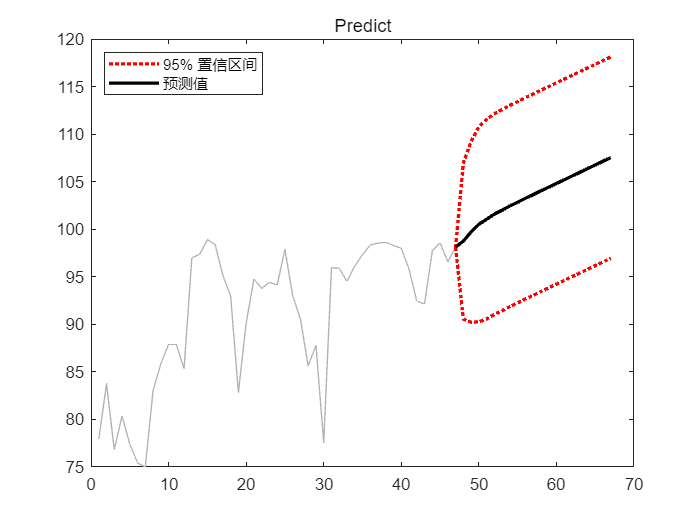

%% 5.预测
step = 20; %预测步数为20
[forData,YMSE] = forecast(EstMdl,step,'Y0',data_t);   
lower = forData - 1.96*sqrt(YMSE); %95置信区间下限
upper = forData + 1.96*sqrt(YMSE); %95置信区间上限

figure()
plot(data_t,'Color',[.7,.7,.7]);
hold on
h1 = plot(length(data_t):length(data_t)+step,[data_t(end);lower],'r:','LineWidth',2);
plot(length(data_t):length(data_t)+step,[data_t(end);upper],'r:','LineWidth',2)
h2 = plot(length(data_t):length(data_t)+step,[data_t(end);forData],'k','LineWidth',2);
legend([h1 h2],'95% 置信区间','预测值',...
	     'Location','NorthWest')
title('Predict')
hold off

上图中灰线为用来训练的37个数据，黑线为未来值的预测，红线为95%置信区间上下限。也就是说未来真实值有95%的概率落在这个范围内。

可以看到使用ARIMA方法进行长期预测的结果是趋势性的。是缓慢递增的。

### 最后，可以看出整体来说预测结果是呈现上升态势的。也与之前的散点图趋势相似。

### 而其他两组数据由于其与沈阳数据相关性较高，也会呈现相同的效果。